clear; close all; clc; 

# **Tool to calculate the complex band structure of PnCs with imported stiffness and mass matrix**

# Settings

di=2;                         %Degrees of freedom per node
PBC0(1,:)=[-0.075, -0.05,0, -0.075, 0.05,0];                  %[Input line coordinates: x1, y1,z1, x2 ,y2,z2].   Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right.  
PBC0(2,:)=[0.075, -0.05,0, 0.075, 0.05,0];                  %[Output line coordinates: x1, y1,z1, x2 ,y2,z2].  Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right. 
PBC0(3,:)=[-0.075, -0.05,0,0.075, -0.05,0];                  %[Input line coordinates: xx1, y1,z1, x2 ,y2,z2].   Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right.  
PBC0(4,:)=[-0.075, 0.05,0, 0.075, 0.05,0];                  %[Output line coordinates: x1, y1,z1, x2 ,y2,z2].  Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right. 
theta=1;                      %ratio lambdax/lambday
minNodeDist=0.0001;                %Minimum node distance to be considered, important for node indexing when line boundary conditions are applied. Usually this value doesnt have to be changed.
OmegC=14000*2*pi;                      %omega intervall end value for calculation of complex band structure
dOmegC=100*2*pi;                     %omega intervall increment value
ParaComp=12;                   %Set parallel computing (yes/no). Parallel computing is only effective for large systems with ~ndof>

# Plot Options

Font="CMU Serif";                       %Font for all plots 
FontSize=26;                   %Font size for all plots 
AxesLineWidth=1;              %Set default axes line width
LineLineWidth=1;              %Set default line width of all lines within plots
MarkerSize1=2;                %Set marker size for complex band structure

# Extracting model information

% model=mphload('ExampleComplexBandStructure.mph'); %Load model from COMSOL
% str = mphmatrix(model, 'sol1', 'out', {'Kc','Ec','K','E'});
% info = mphxmeshinfo(model);
% Ksys=sparse(str.K);                           %full stiffness matrix
% Msys=sparse(str.E);                           %full mass matrix
% InitialNodes = [info.nodes.coords', zeros(size(info.nodes.coords',1),1)];
% % InitialNodes=info.dofs.coords';
% % InitialNodes=InitialNodes(1:2:end,:);
% % InitialNodes=[InitialNodes, zeros(size(InitialNodes,1),1)];
% numDoF=info.ndofs;
load model_information.mat;

# Calculation   

[IdxPBCIn,IdxPBCOut,PBCTrans,BasisVec]=IndexPBC3D(InitialNodes,di,PBC0,minNodeDist);  
i=sqrt(-1);
numredDoF=numDoF-size(unique(IdxPBCOut),1);
redDoF=1:numDoF;
redDoF(:,unique(IdxPBCOut))=[];
SIdxPBCIn=unique(sort(reshape(IdxPBCIn,[],1)));
SIdxPBCOut=unique(sort(reshape(IdxPBCOut,[],1)));
SlaveDofsPBC=1:numDoF;
SlaveDofsPBC([SIdxPBCIn,SIdxPBCOut])=[];
CompNodes=InitialNodes;
CompNodes(unique(ceil(SlaveDofsPBC/di)),:)=[];
[IdxPBCCompIn,IdxPBCCompOut,PBCCompTrans,~]=IndexPBC3D(CompNodes,di,PBC0,minNodeDist);
tic
updateWaitbarCompBands = waitbarParfor(ceil(OmegC/dOmegC)+1, "Calculation of complex band structure in progress...")

updateWaitbarCompBands = function_handle with value:
    @waitbarParfor/updateProxy


% for idxComp=1:ceil(OmegC/dOmegC)+1
parfor (idxComp=1:ceil(OmegC/dOmegC)+1,ParaComp)
    omegComp=dOmegC*(idxComp-1)+0.1;
    KdynPBC=Ksys-omegComp^2*Msys;
    [KdynPBCred,~,~,~,~]=FastGuyanReduction(KdynPBC,KdynPBC,KdynPBC,SlaveDofsPBC);
%     [K3GX, K4GX, K3XM, K4XM, K1MG, K2MG, K3MG,K1MGq, K2MGq]=CoefficientMatricesPBCrecUC_marius(KdynPBCred,IdxPBCCompIn,IdxPBCCompOut,PBCCompTrans,theta);
    [K3GX, K4GX, K3XM, K4XM, K1MG, K2MG, K3MG, ~, ~, ~, ~]=CoefficientMatricesPBCrect(KdynPBCred,IdxPBCCompIn,IdxPBCCompOut,PBCCompTrans,theta);
    lambXiGX = quadeig(K3GX,K4GX,transpose(K3GX));
    kxSCGX0{idxComp}=i*log(lambXiGX);

    if size(BasisVec,1)>1
        lambXiXM = quadeig(K3XM,K4XM,transpose(K3XM));
        lambXiMG = polyeig(transpose(K1MG),transpose(K2MG),K3MG,K2MG,K1MG);
        kxSCXM0{idxComp}=i*log(lambXiXM);
        kxSCMG0{idxComp}=i*log(lambXiMG);
    end

    updateWaitbarCompBands(); 
end

CompBandStepTime=toc;
CompBandStepTime=CompBandStepTime/(ceil(OmegC/dOmegC)+1);
kxSCGX=cell2mat(kxSCGX0);

if size(BasisVec,1)>1
    kxSCXM=cell2mat(kxSCXM0);
    kxSCMG=cell2mat(kxSCMG0);
end

fprintf(['Calculation time for one frequency step is approximately ',num2str(CompBandStepTime), ' [s].', '\n'])

Calculation time for one frequency step is approximately 0.026617 [s].


[kxSCGXRe, kxSCGXIm, kxSCGXCom] = filterCBS_2DFEM(kxSCGX);
[kxSCXMRe, kxSCXMIm, kxSCXMCom] = filterCBS_2DFEM(kxSCXM);
[kxSCMGRe, kxSCMGIm, kxSCMGCom] = filterCBS_2DFEM(kxSCMG);
PRekxSCGX=real(kxSCGXRe);
PRekxSCXM=real(kxSCXMRe);
PRekxSCMG=real(kxSCMGRe);
CRekxSCGX=real(kxSCGXCom);
CRekxSCXM=real(kxSCXMCom);
CRekxSCMG=real(kxSCMGCom);
RImkxSCGX=imag(kxSCGXRe);
RImkxSCXM=imag(kxSCXMRe);
RImkxSCMG=imag(kxSCMGRe);
PImkxSCGX=imag(kxSCGXIm);
PImkxSCXM=imag(kxSCXMIm);
PImkxSCMG=imag(kxSCMGIm);
CImkxSCGX=imag(kxSCGXCom);
CImkxSCXM=imag(kxSCXMCom);
CImkxSCMG=imag(kxSCMGCom);
omegSCGX=repmat([0.1:dOmegC:OmegC+0.1]/(2*pi),size(kxSCGXRe,1),1);
omegSCXM=repmat([0.1:dOmegC:OmegC+0.1]/(2*pi),size(kxSCXMRe,1),1);
omegSCMG=repmat([0.1:dOmegC:OmegC+0.1]/(2*pi),size(kxSCMGRe,1),1);

# Plot Dispersion curves

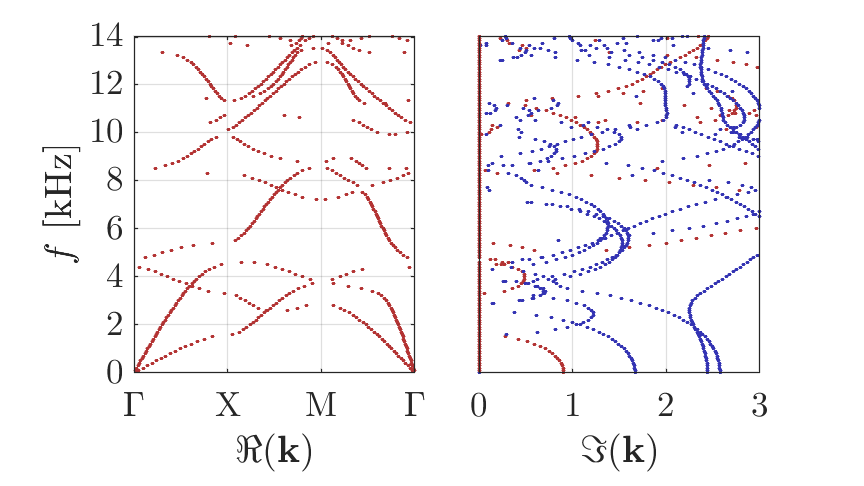

set(0, 'DefaultAxesLineWidth', AxesLineWidth);
set(0, 'DefaultLineLineWidth', LineLineWidth);

DRed=[0.70 0.2 0.2];                   %Dark Red
DBlue=[.2 .2 0.7];                     %Dark Blue 

figure

set(gcf, 'Position',  [0, 0, 1920/2*0.9, 1080/2*0.9])
tilpltBG = tiledlayout(1,2,'TileSpacing','none');

nexttile(tilpltBG)

hold on

CompFreqBandsPRe1=plot(PRekxSCGX(round(PRekxSCGX,3)>0&round(PRekxSCGX,3)~=round(pi,3))/pi, omegSCGX(round(PRekxSCGX,3)>0&round(PRekxSCGX,3)~=round(pi,3)),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsPRe2=plot(PRekxSCXM(round(PRekxSCXM,3)>0&round(PRekxSCXM,3)~=round(pi,3))/pi+1, omegSCXM(round(PRekxSCXM,3)>0&round(PRekxSCXM,3)~=round(pi,3)),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsPRe3=plot(-PRekxSCMG(round(PRekxSCMG,3)>0&round(PRekxSCMG,3)~=round(pi,3))/pi+3, omegSCMG(round(PRekxSCMG,3)>0&round(PRekxSCMG,3)~=round(pi,3)),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
% CompFreqBandsCRe1=plot(CRekxSCGX(round(CRekxSCGX,3)>0&round(CRekxSCGX,3)~=round(pi,3))/pi, omegSCGX(round(CRekxSCGX,3)>0&round(CRekxSCGX,3)~=round(pi,3)),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DBlue,'MarkerEdgeColor',DBlue,'LineStyle','none');
% CompFreqBandsCRe2=plot(CRekxSCXM(round(CRekxSCXM,3)>0&round(CRekxSCXM,3)~=round(pi,3))/pi+1, omegSCXM(round(CRekxSCXM,3)>0&round(CRekxSCXM,3)~=round(pi,3)),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DBlue,'MarkerEdgeColor',DBlue,'LineStyle','none');
% CompFreqBandsCRe3=plot(-CRekxSCMG(round(CRekxSCMG,3)>0&round(CRekxSCMG,3)~=round(pi,3))/pi+3, omegSCMG(round(CRekxSCMG,3)>0&round(CRekxSCMG,3)~=round(pi,3)),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DBlue,'MarkerEdgeColor',DBlue,'LineStyle','none');

axis([0 3 0 (OmegC+0.1)/(2*pi)]);
xticks([0:1:3])% create tick marks at 1/4 multiples of pi
xticklabels({'\Gamma', 'X', 'M','\Gamma'})

% end
box on

set(gca,'Layer','top')
pbaspect([1 1.2 1]);
xlabel('$\Re(\bf{k})$','interpreter', 'latex')
ylabel('$f$ [kHz]','interpreter', 'latex')
yticks([0:2000:14000])
yticklabels([0 2 4 6 8 10 12 14])
grid on
figureHandle = gcf;
set(findall(figureHandle,'type','text'),'fontSize',FontSize,'fontWeight','normal','fontName',Font)
set(findall(figureHandle,'type','axes'),'fontsize',FontSize,'fontWeight','normal','fontName',Font)
hold off
nexttile(tilpltBG)
set(gcf, 'Position',  [0, 0, 1920/2*0.9, 1080/2*0.9])
hold on

CompFreqBandsPIm1=plot(PImkxSCGX, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsPIm2=plot(PImkxSCXM, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsPIm3=plot(PImkxSCMG, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsCIm1=plot(CImkxSCGX, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DBlue,'MarkerEdgeColor',DBlue,'LineStyle','none');
CompFreqBandsCIm2=plot(CImkxSCXM, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DBlue,'MarkerEdgeColor',DBlue,'LineStyle','none');
CompFreqBandsCIm3=plot(CImkxSCMG, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DBlue,'MarkerEdgeColor',DBlue,'LineStyle','none');
CompFreqBandsRIm1=plot(RImkxSCGX, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsRIm2=plot(RImkxSCXM, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
CompFreqBandsRIm3=plot(RImkxSCMG, [0.1:dOmegC:OmegC+0.1]/(2*pi),'-ok','MarkerSize',MarkerSize1,'MarkerFaceColor',DRed,'MarkerEdgeColor',DRed,'LineStyle','none');
    
axis([0 3 0 (OmegC+0.1)/(2*pi)]);

hold off

pbaspect([1 1.2 1]);

grid on

xlabel('$\Im(\bf{k})$','interpreter', 'latex')
figureHandle = gcf;

set(findall(figureHandle,'type','text'),'fontSize',FontSize,'fontWeight','normal','fontName',Font)
set(findall(figureHandle,'type','axes'),'fontsize',FontSize,'fontWeight','normal','fontName',Font)
set(gca,'ytick',[])
set(gca,'yticklabel',[])

box on

set(gca,'Layer','top')

tilplt.TileSpacing = 'none';
tilplt.Padding = 'none';
